## c) Eddies Secret Function

hold off; close;
eddieSecretFunction([1,2])

ans =   104.3045   98.3045


eddieSecretFunction([-1,-2]')

ans = 235.2101

eddieSecretFunction([-1,-2]')

ans = 361.4544

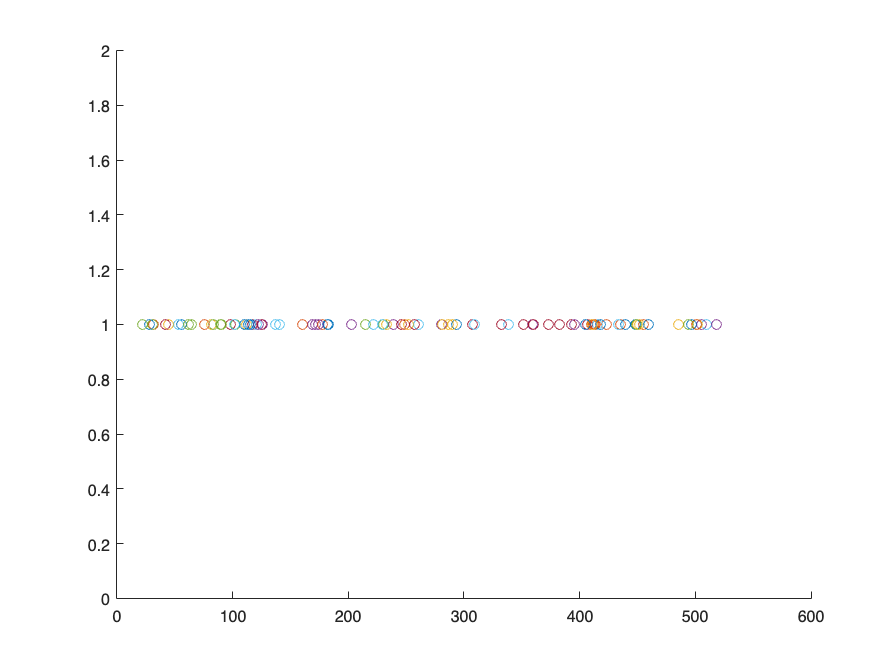

hold on;
for i = 1:100
    x = eddieSecretFunction([0,0]');
    scatter(x,1);
    X(i) = x;
end
hold off;

% plot
x = linspace(-100,100,100);
y = linspace(-100,100,100);
[X,Y] = meshgrid(x,y);

for i = 1:length(x)
    for ii = 1:length(y)
        Z(i,ii) = fun([X(i,ii),Y(i,ii)]);
    end
end

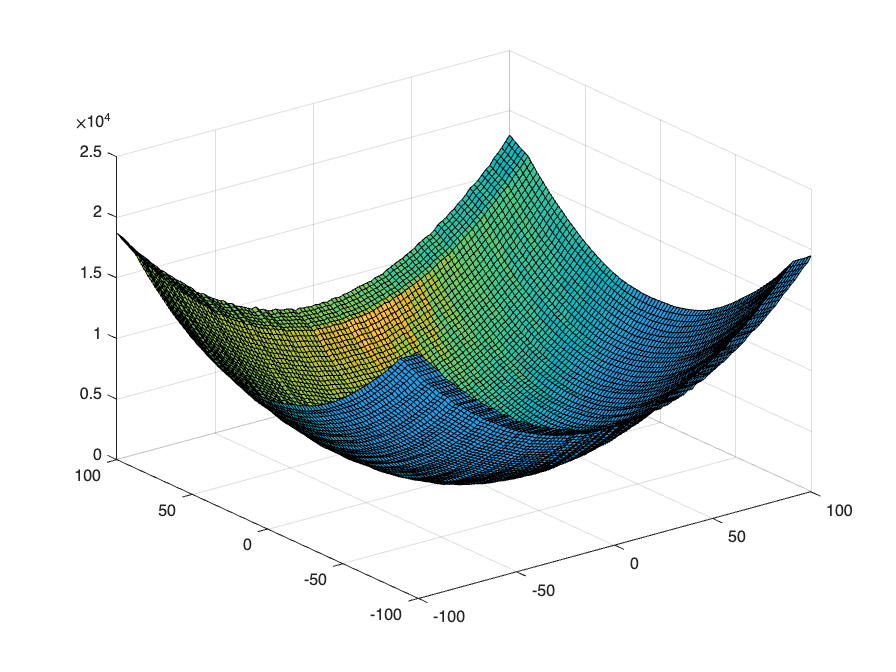

% Smooth input data
Z = smoothdata(Z,"movmean","SmoothingFactor",0.15);
surfl(X,Y,Z)

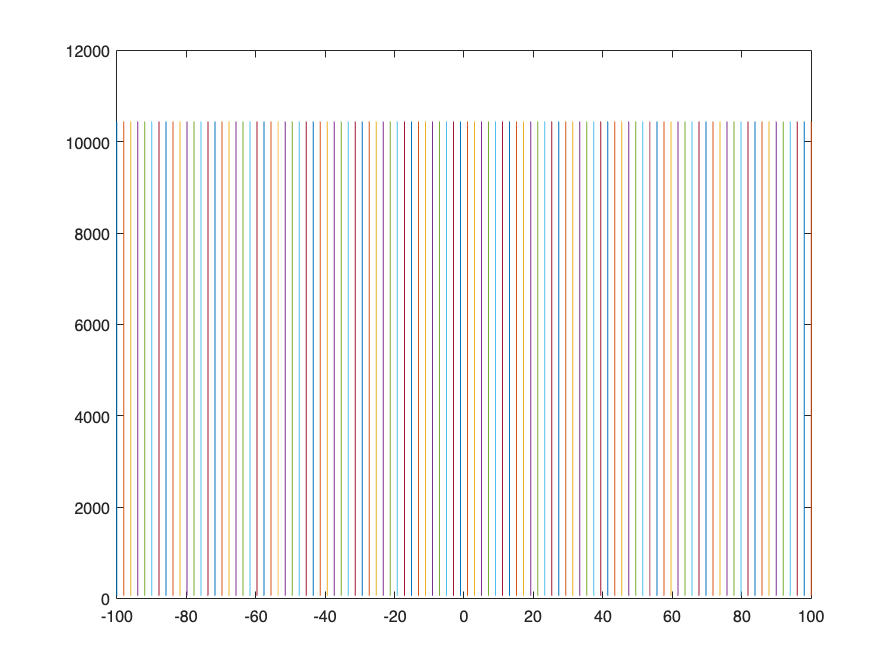

% look at cross section
y = 0;
for i = 1:length(x)
    Z_cross(i) = fun([x(i),0]);
end
plot([X,Z_cross],'-');

### The function is clearly non-linear and stochastic, it may also be non-smooth and so that narrows down the global optimisation methods that can be used:

- Particle Swarm

- Genetic Algorithms

- Simulated Annealing

- and others

Since I have already looked at Particle Swarm optimisation I will first try optimisation using PSO.

Main issues:

- input to function must be one variable, this is addressed in fun line.

- output from function must be a single value, inputting a vertical column vector outputs a single scalar value.

fun = @(x)(eddieSecretFunction([x(1),x(2)]'));

lb = [-100,-100];
ub = [100,100];

% Minimising using particle swarm
options = optimoptions("particleswarm","MaxIterations",600,"SwarmSize",1500);
[x, fval] = particleswarm(fun,2,lb,ub,options)

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x =     3.0237    3.9639


fval = 1.6317

% minimising using GA
GAoptions = optimoptions("ga","MaxGenerations",600,"PopulationSize",1500);
[x,fval] = ga(fun,2,[],[],[],[],lb,ub,[],[],GAoptions)

Optimization terminated: maximum number of generations exceeded.


x =     1.9494    3.9281


fval = 2.4618

After a few attempts with Particle Swarm and Genetic Algorithms with similar parameters, the algorithms tend to find a similar minimum value in a similar area, however they do not converge on the same point. The area in question can be looked at more closely:

lb = [0,0];
ub = [5,5];

[x, fval] = particleswarm(fun,2,lb,ub,options)

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x =     1.9803    4.9987


fval = 1.0967

[x,fval] = ga(fun,2,[],[],[],[],lb,ub,[],[],GAoptions)

Optimization terminated: maximum number of generations exceeded.


x =     2.0177    4.0440


fval = 0.5103

In this area the GA appears to handle the optimisation better, narrowing in around (2,4) area.

Try and plot: